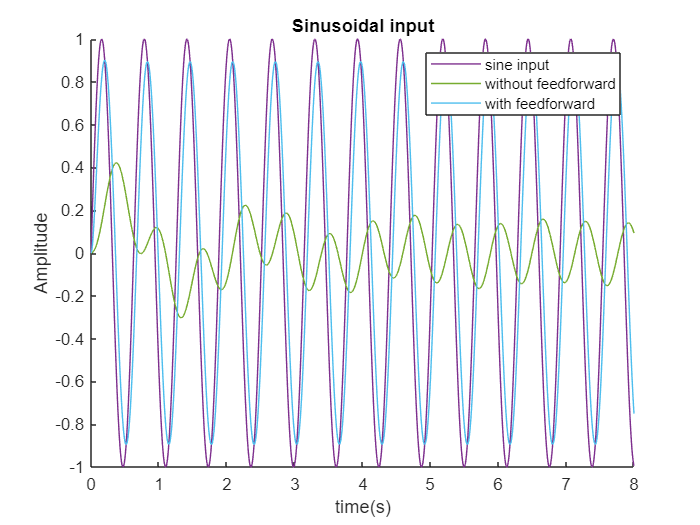

syms s

R = 10/(s^2+100);
T = (s+9)/(s^2+s+9);
Y = R*T;
Y1 = (R)/(0.05*s+1);

r = ilaplace(R);
y = ilaplace(Y);
y1 = ilaplace(Y1);

title("Sinusoidal input")
xlabel("time(s)")
ylabel("Amplitude")
t = 8;
hold on;
fplot(r,[0 t])
fplot(y,[0 t])
fplot(y1,[0 t])
legend([fplot(r,[0 t]),fplot(y,[0 t]),fplot(y1,[0 t])], ["sine input", "without feedforward", "with feedforward"]);